% clear all
% data = readmatrix("data/Essai_1704_Test2.csv");
% data = data(:,1:8);
% fs = 250; %fréquence d'échantillonnage
% fc1 = 12;
% fc2 = 35;
% N = 75000;
% decompte = 5*250;
% nn = N/25;
% ii = 0;
% time = linspace(0,7*8);
% 
% for i = 0:24
%     startIndexCroix = int32(decompte + nn*i);
%     endIndexCroix = int32(decompte + nn*i + 5*250);
%     startIndexSignal = int32(endIndexCroix);
%     endIndexSignal = int32(startIndexSignal + 7*250);
% 
%     croix = data(startIndexCroix:endIndexCroix,:);
%     if mod(i,2) == 0
%         label = 'Droite';
%         mouvement = data(startIndexSignal:endIndexSignal, :);
%         droite = [mouvement(:,1);...
%             mouvement(:,2);...
%             mouvement(:,3);...
%             mouvement(:,4);...
%             mouvement(:,5);...
%             mouvement(:,6);...
%             mouvement(:,7);...
%             mouvement(:,8)];
%         duration = length(droite) / fs;
%         time = linspace(0, duration, length(droite));
%         figure;
%         plot(time,droite)
%         title('Signal mouvement main droite');xlabel('Time (s)');ylabel('Amplitude');
%     else
%         label = 'Gauche';
%         mouvement = data(startIndexSignal:endIndexSignal, :);
%         gauche = [mouvement(:,1);...
%             mouvement(:,2);...
%             mouvement(:,3);...
%             mouvement(:,4);...
%             mouvement(:,5);...
%             mouvement(:,6);...
%             mouvement(:,7);...
%             mouvement(:,8)];
%         duration = length(gauche) / fs;
%         time = linspace(0, duration, length(gauche));
%         figure;
%         plot(time,gauche)
%         title('Signal mouvement main gauche');xlabel('Time (s)');ylabel('Amplitude');
%     end
% end

% clear all
% data = readmatrix("data/Essai_1704_Test2.csv");
% data = data(:,1:8);
% fs = 250; %fréquence d'échantillonnage
% fc1 = 12;
% fc2 = 35;
% N = 75000;
% decompte = 5*250;
% nn = N/25;
% ii = 0;
% 
% % Création de la figure pour les mouvements de la main droite
% figure;
% sgtitle('Signaux mouvements main droite avant filtrage');
% for i = 0:24
%     startIndexCroix = int32(decompte + nn*i);
%     endIndexCroix = int32(decompte + nn*i + 5*250);
%     startIndexSignal = int32(endIndexCroix);
%     endIndexSignal = int32(startIndexSignal + 7*250);
% 
%     croix = data(startIndexCroix:endIndexCroix,:);
%     if mod(i,2) == 0
%         label = 'Droite';
%         mouvement = data(startIndexSignal:endIndexSignal, :);
%         droite = [mouvement(:,1);...
%             mouvement(:,2);...
%             mouvement(:,3);...
%             mouvement(:,4);...
%             mouvement(:,5);...
%             mouvement(:,6);...
%             mouvement(:,7);...
%             mouvement(:,8)];
%         duration = length(droite) / fs;
%         time = linspace(0, duration, length(droite));
%         subplot(5,3,i/2+1);
%         plot(time,droite)
%         title(sprintf('Signal mouvement %s %d', label, i/2+1));
%         xlabel('Time (s)');ylabel('Amplitude');
%     end
% end
% 
% % Création de la figure pour les mouvements de la main gauche
% figure;
% sgtitle('Signaux mouvements main gauche avant filtrage');
% for i = 0:24
%     startIndexCroix = int32(decompte + nn*i);
%     endIndexCroix = int32(decompte + nn*i + 5*250);
%     startIndexSignal = int32(endIndexCroix);
%     endIndexSignal = int32(startIndexSignal + 7*250);
% 
%     croix = data(startIndexCroix:endIndexCroix,:);
%     if mod(i,2) ~= 0
%         label = 'Gauche';
%         mouvement = data(startIndexSignal:endIndexSignal, :);
%         gauche = [mouvement(:,1);...
%             mouvement(:,2);...
%             mouvement(:,3);...
%             mouvement(:,4);...
%             mouvement(:,5);...
%             mouvement(:,6);...
%             mouvement(:,7);...
%             mouvement(:,8)];
%         duration = length(gauche) / fs;
%         time = linspace(0, duration, length(gauche));
%         subplot(5,3,(i-1)/2+1);
%         plot(time,gauche)
%         title(sprintf('Signal mouvement %s %d', label, (i-1)/2+1));
%         xlabel('Time (s)');ylabel('Amplitude');
%     end
% end

## Tracé des signaux filtrés un à un puis concaténés

clear all
data = readmatrix("data/Essai_1704_Test3.csv");
data = data(:,1:4);
fs = 250; %fréquence d'échantillonnage
fc1 = 12;
fc2 = 35;
N = 75000;
decompte = 5*250;
nn = N/25;
ii = 0;

% Création de la figure pour les mouvements de la main droite
figure;
sgtitle('Signaux mouvements main droite après filtrage');
for i = 0:24
    startIndexCroix = int32(decompte + nn*i);
    endIndexCroix = int32(decompte + nn*i + 5*250);
    startIndexSignal = int32(endIndexCroix);
    endIndexSignal = int32(startIndexSignal + 7*250);

    croix = data(startIndexCroix:endIndexCroix,:);
    if mod(i,2) == 0
        label = 'Droite';
        mouvement = data(startIndexSignal:endIndexSignal, :);
        [b,a] = butter(4,fc2/(fs/2),"high"); %filtre passe-haut (supprimer bruit à basse fréquence)
%         eeg_data_filtered = filtfilt(b,a,gauche); % appliquer filtre aux données EEG
        eeg_data_filtered = filter(b,a,mouvement); % appliquer filtre aux données EEG

        [b,a] = butter(4,fc1/(fs/2),"low"); %filtre passe-bas (supprimer bruit à haute fréquence)
%         eeg_data_filtered = filtfilt(b,a, eeg_data_filtered);
        eeg_data_filtered = filter(b,a, eeg_data_filtered);

        droite = [eeg_data_filtered(:,1);...
            eeg_data_filtered(:,2);...
            eeg_data_filtered(:,3);...
            eeg_data_filtered(:,4)];

        duration = length(droite) / fs;
        time = linspace(0, duration, length(droite));
        subplot(5,3,i/2+1);
        plot(time,droite)
        title(sprintf('Signal mouvement %s %d', label, i/2+1));
        xlabel('Time (s)');ylabel('Amplitude');
    end
end

% Création de la figure pour les mouvements de la main gauche
figure;
sgtitle('Signaux mouvements main gauche après filtrage');
for i = 0:24
    startIndexCroix = int32(decompte + nn*i);
    endIndexCroix = int32(decompte + nn*i + 5*250);
    startIndexSignal = int32(endIndexCroix);
    endIndexSignal = int32(startIndexSignal + 7*250);

    croix = data(startIndexCroix:endIndexCroix,:);
    if mod(i,2) ~= 0
        label = 'Gauche';
        mouvement = data(startIndexSignal:endIndexSignal, :);

        [b,a] = butter(4,fc2/(fs/2),"high"); %filtre passe-haut (supprimer bruit à basse fréquence)
%         eeg_data_filtered = filtfilt(b,a,gauche); % appliquer filtre aux données EEG
        eeg_data_filtered = filter(b,a,mouvement); % appliquer filtre aux données EEG

        [b,a] = butter(4,fc1/(fs/2),"low"); %filtre passe-bas (supprimer bruit à haute fréquence)
%         eeg_data_filtered = filtfilt(b,a, eeg_data_filtered);
        eeg_data_filtered = filter(b,a, eeg_data_filtered);

        gauche = [eeg_data_filtered(:,1);...
            eeg_data_filtered(:,2);...
            eeg_data_filtered(:,3);...
            eeg_data_filtered(:,4)];

        duration = length(gauche) / fs;
        time = linspace(0, duration, length(gauche));
        subplot(5,3,i/2+1);
        plot(time,gauche)
        title(sprintf('Signal mouvement %s %d', label, (i-1)/2+1));
        xlabel('Time (s)');ylabel('Amplitude');
    end
end

## Tracé des signaux électrodes par électrodes

clear all
data = readmatrix("data/Essai_1704_Test3.csv");
data = data(:,1:4);
fs = 250; %fréquence d'échantillonnage
fc1 = 12;
fc2 = 35;
N = 75000;
decompte = 5*250;
nn = N/25;
ii = 0;

% Création de la figure pour les mouvements de la main droite

for i = 0:24
    startIndexCroix = int32(decompte + nn*i);
    endIndexCroix = int32(decompte + nn*i + 5*250);
    startIndexSignal = int32(endIndexCroix);
    endIndexSignal = int32(startIndexSignal + 7*250);

    croix = data(startIndexCroix:endIndexCroix,:);
    if mod(i,2) == 0
        label = 'Droite';
        mouvement = data(startIndexSignal:endIndexSignal, :);

        [b,a] = butter(4,fc2/(fs/2),"high"); %filtre passe-haut (supprimer bruit à basse fréquence)
        eeg_data_filtered = filter(b,a,mouvement); % appliquer filtre aux données EEG

        [b,a] = butter(4,fc1/(fs/2),"low"); %filtre passe-bas (supprimer bruit à haute fréquence)
        eeg_data_filtered = filter(b,a, eeg_data_filtered);

        duration = length(eeg_data_filtered) / fs;
        time = linspace(0, duration, length(eeg_data_filtered));
        figure;
        subplot(4,1,1);
        plot(time,eeg_data_filtered(:,1));
        title('Signaux électrodes main droite');
        xlabel('Temps (s)');
        ylabel('Amplitude');
        subplot(4,1,2);
        plot(time,eeg_data_filtered(:,2));
        title('Signaux électrodes main droite');
        xlabel('Temps (s)');
        ylabel('Amplitude');
        subplot(4,1,3);
        plot(time,eeg_data_filtered(:,3));
        title('Signaux électrodes main droite');
        xlabel('Temps (s)');
        ylabel('Amplitude');
        subplot(4,1,4);
        plot(time,eeg_data_filtered(:,4));
        title('Signaux électrodes main droite');
        xlabel('Temps (s)');
        ylabel('Amplitude');
    end
end

clear all
data = readmatrix("data/Marion/Essai_1704_Test3.csv");
data = data(:,1:4);
fs = 250; %fréquence d'échantillonnage
fc1 = 12;
fc2 = 35;
N = 75000;
decompte = 5*250;
nn = N/25;
ii = 0;


for i = 0:24
    startIndexCroix = int32(decompte + nn*i);
    endIndexCroix = int32(decompte + nn*i + 5*250);
    startIndexSignal = int32(endIndexCroix);
    endIndexSignal = int32(startIndexSignal + 7*250);

    croix = data(startIndexCroix:endIndexCroix,:);
    if mod(i,2) ~= 0
        label = 'Gauche';
        mouvement = data(startIndexSignal:endIndexSignal, :);

%         [b,a] = butter(4,fc2/(fs/2),"high"); %filtre passe-haut (supprimer bruit à basse fréquence)
%         eeg_data_filtered = filter(b,a,mouvement); % appliquer filtre aux données EEG
% 
%         [b,a] = butter(4,fc1/(fs/2),"low"); %filtre passe-bas (supprimer bruit à haute fréquence)
%         eeg_data_filtered = filter(b,a, eeg_data_filtered);

        duration = length(mouvement) / fs;
        time = linspace(0, duration, length(mouvement));
        figure;
        subplot(4,1,1);
        plot(time,mouvement(:,1));
        title('Signaux électrodes main gauche');
        xlabel('Temps (s)');
        ylabel('Amplitude');
        subplot(4,1,2);
        plot(time,mouvement(:,2));
        title('Signaux électrodes main gauche');
        xlabel('Temps (s)');
        ylabel('Amplitude');
        subplot(4,1,3);
        plot(time,mouvement(:,3));
        title('Signaux électrodes main gauche');
        xlabel('Temps (s)');
        ylabel('Amplitude');
        subplot(4,1,4);
        plot(time,mouvement(:,4));
        title('Signaux électrodes main gauche');
        xlabel('Temps (s)');
        ylabel('Amplitude');
    end
end

## Signaux individuels Marion

clear all
%Meilleures données droite 2,
data = readmatrix("data/Marion/Essai_1804_Droite2.csv");

data = data(:,1:4);
fs = 250; %fréquence d'échantillonnage
fc1 = 12;
fc2 = 35;
N = length(data);
decompte = 3*250;
nn = (N-decompte)/13;
ii = 0;


% Création de la figure pour les mouvements de la main droite
figure;
sgtitle('Signaux mouvements main droite après filtrage');
for i = 0:12

    startIndexCroix = int32(decompte + nn*i);
    endIndexCroix = int32(decompte + nn*i + 7*250);
    startIndexSignal = int32(endIndexCroix);
    endIndexSignal = int32(startIndexSignal + 7*250);

    croix = data(startIndexCroix:endIndexCroix,:);

    label = 'Droite';
    mouvement = data(startIndexSignal:endIndexSignal, :);
    [b,a] = butter(4,fc2/(fs/2),"high"); %filtre passe-haut (supprimer bruit à basse fréquence)
%         eeg_data_filtered = filtfilt(b,a,gauche); % appliquer filtre aux données EEG
    eeg_data_filtered = filter(b,a,mouvement); % appliquer filtre aux données EEG

    [b,a] = butter(4,fc1/(fs/2),"low"); %filtre passe-bas (supprimer bruit à haute fréquence)
%         eeg_data_filtered = filtfilt(b,a, eeg_data_filtered);
    eeg_data_filtered = filter(b,a, eeg_data_filtered);

    droite = [eeg_data_filtered(:,1);...
        eeg_data_filtered(:,2);...
        eeg_data_filtered(:,3);...
        eeg_data_filtered(:,4)];

    duration = length(droite) / fs;
    time = linspace(0, duration, length(droite));
    subplot(5,3,i+1);
    plot(time,droite)
    title(sprintf('Signal mouvement %s %d', label, i+1));
    xlabel('Time (s)');ylabel('Amplitude');

end
%Meilleures données gauche 3,
data = readmatrix("data/Marion/Essai_1904_Gauche6.csv");
data = data(:,1:4);
% Création de la figure pour les mouvements de la main gauche
figure;
sgtitle('Signaux mouvements main gauche après filtrage');
for i = 0:12
    startIndexCroix = int32(decompte + nn*i);
    endIndexCroix = int32(decompte + nn*i + 5*250);
    startIndexSignal = int32(endIndexCroix);
    endIndexSignal = int32(startIndexSignal + 7*250);

    croix = data(startIndexCroix:endIndexCroix,:);

    label = 'Gauche';
    mouvement = data(startIndexSignal:endIndexSignal, :);

    [b,a] = butter(4,fc2/(fs/2),"high"); %filtre passe-haut (supprimer bruit à basse fréquence)
%         eeg_data_filtered = filtfilt(b,a,gauche); % appliquer filtre aux données EEG
    eeg_data_filtered = filter(b,a,mouvement); % appliquer filtre aux données EEG

    [b,a] = butter(4,fc1/(fs/2),"low"); %filtre passe-bas (supprimer bruit à haute fréquence)
%         eeg_data_filtered = filtfilt(b,a, eeg_data_filtered);
    eeg_data_filtered = filter(b,a, eeg_data_filtered);

    gauche = [eeg_data_filtered(:,1);...
        eeg_data_filtered(:,2);...
        eeg_data_filtered(:,3);...
        eeg_data_filtered(:,4)];

    duration = length(gauche) / fs;
    time = linspace(0, duration, length(gauche));
    subplot(5,3,i+1);
    plot(time,gauche)
    title(sprintf('Signal mouvement %s %d', label, i+1));
    xlabel('Time (s)');ylabel('Amplitude');
end

## Tracé de signaux avec seulement les electrodes C3 et C4, scalogrammes avant et après filtrage

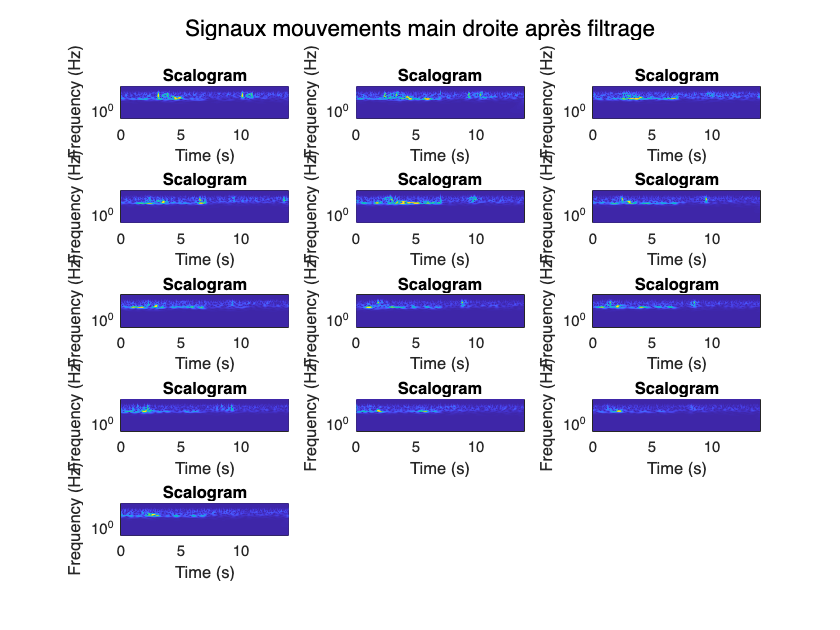

clear all
%Meilleures données droite 2,
data = readmatrix("data/Marion/Essai_1804_Droite2.csv");

data = data(:,1:4);
fs = 250; %fréquence d'échantillonnage
fc1 = 12;
fc2 = 35;
N = length(data);
decompte = 3*250;
nn = (N-decompte)/13;
ii = 0;


% Création de la figure pour les mouvements de la main droite (filtres)
figure;
sgtitle('Signaux mouvements main droite après filtrage');
for i = 0:12
    
    startIndexCroix = int32(decompte + nn*i);
    endIndexCroix = int32(decompte + nn*i + 7*250);
    startIndexSignal = int32(endIndexCroix);
    endIndexSignal = int32(startIndexSignal + 7*250);
    
    label = 'Droite';
    mouvement = data(startIndexSignal:endIndexSignal, :);
    droite = [mouvement(:,2);...
        mouvement(:,4)];
    
    [b,a] = butter(4,fc2/(fs/2),"high"); %filtre passe-haut (supprimer bruit à basse fréquence)
    eeg_data_filtered = filter(b,a,droite); % appliquer filtre aux données EEG
    
    [b,a] = butter(4,fc1/(fs/2),"low"); %filtre passe-bas (supprimer bruit à haute fréquence)
    eeg_data_filtered = filter(b,a, eeg_data_filtered);
    
    subplot(5,3,i+1);
    fb = cwtfilterbank(signallength = length(eeg_data_filtered),...
                samplingfrequency=fs, ...
                wavelet="Morse");
    [cfs,frq] = wt(fb,eeg_data_filtered);

    %Tracé du scalogramme
    t = (0:(length(eeg_data_filtered)-1))/fs;
    pcolor(t,frq,abs(cfs));
    set(gca,'yscale','log');shading interp;axis tight;
    title('Scalogram');xlabel('Time (s)');ylabel('Frequency (Hz)');
end

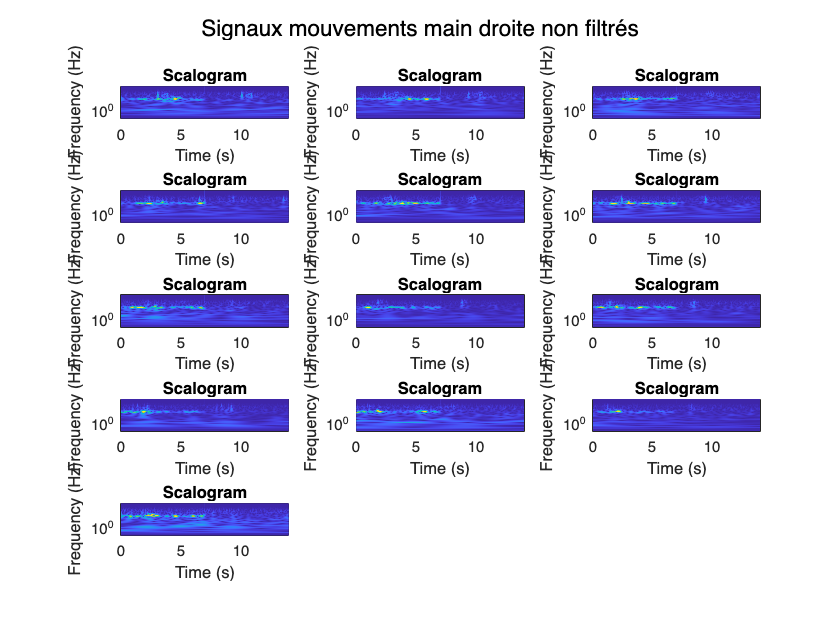


% Création de la figure pour les mouvements de la main droite (non filtrés)
figure;
sgtitle('Signaux mouvements main droite non filtrés');
for i = 0:12
    
    startIndexCroix = int32(decompte + nn*i);
    endIndexCroix = int32(decompte + nn*i + 7*250);
    startIndexSignal = int32(endIndexCroix);
    endIndexSignal = int32(startIndexSignal + 7*250);
    
    label = 'Droite';
    mouvement = data(startIndexSignal:endIndexSignal, :);
    droite = [mouvement(:,2);...
        mouvement(:,4)];
    
    subplot(5,3,i+1);
    fb = cwtfilterbank(signallength = length(droite),...
                samplingfrequency=fs, ...
                wavelet="Morse");
    [cfs,frq] = wt(fb,droite);
    %Tracé du scalogramme
    t = (0:(length(droite)-1))/fs;
    pcolor(t,frq,abs(cfs));
    set(gca,'yscale','log');shading interp;axis tight;
    title('Scalogram');xlabel('Time (s)');ylabel('Frequency (Hz)');
end

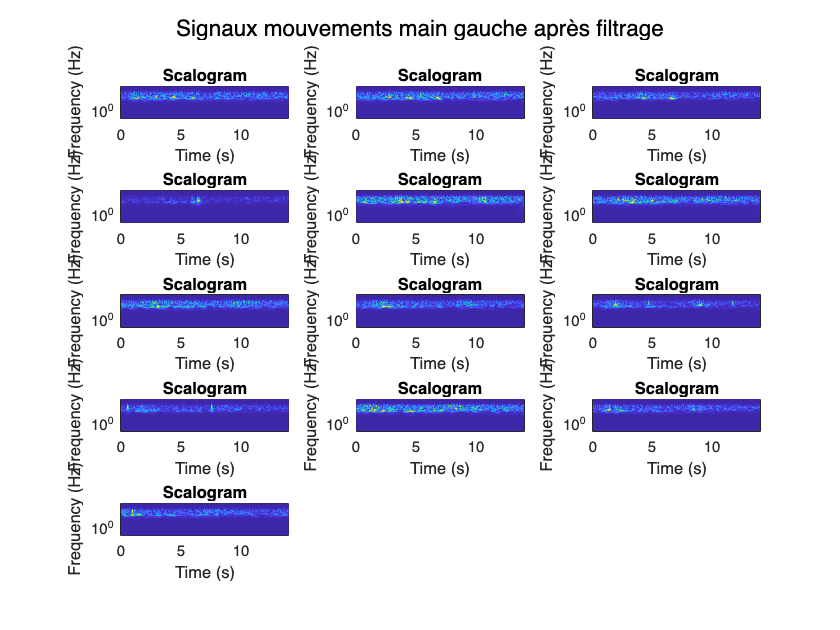

clear all
%Meilleures données gauche 3,
data = readmatrix("data/Marion/Essai_1804_Gauche3.csv");
data = data(:,1:4);
data = data(:,1:4);
fs = 250; %fréquence d'échantillonnage
fc1 = 12;
fc2 = 35;
N = length(data);
decompte = 3*250;
nn = (N-decompte)/13;
ii = 0;
% Création de la figure pour les mouvements de la main gauche (filtres)
figure;
sgtitle('Signaux mouvements main gauche après filtrage');
for i = 0:12
    
    startIndexCroix = int32(decompte + nn*i);
    endIndexCroix = int32(decompte + nn*i + 7*250);
    startIndexSignal = int32(endIndexCroix);
    endIndexSignal = int32(startIndexSignal + 7*250);
    
    label = 'Gauche';
    mouvement = data(startIndexSignal:endIndexSignal, :);
    gauche = [mouvement(:,2);...
        mouvement(:,4)];
    
    [b,a] = butter(4,fc2/(fs/2),"high"); %filtre passe-haut (supprimer bruit à basse fréquence)
    eeg_data_filtered = filter(b,a,gauche); % appliquer filtre aux données EEG
    
    [b,a] = butter(4,fc1/(fs/2),"low"); %filtre passe-bas (supprimer bruit à haute fréquence)
    eeg_data_filtered = filter(b,a, eeg_data_filtered);
    
    subplot(5,3,i+1);
    fb = cwtfilterbank(signallength = length(eeg_data_filtered),...
                samplingfrequency=fs, ...
                wavelet="Morse");
    [cfs,frq] = wt(fb,eeg_data_filtered);

    %Tracé du scalogramme
    t = (0:(length(eeg_data_filtered)-1))/fs;
    pcolor(t,frq,abs(cfs));
    set(gca,'yscale','log');shading interp;axis tight;
    title('Scalogram');xlabel('Time (s)');ylabel('Frequency (Hz)');
end

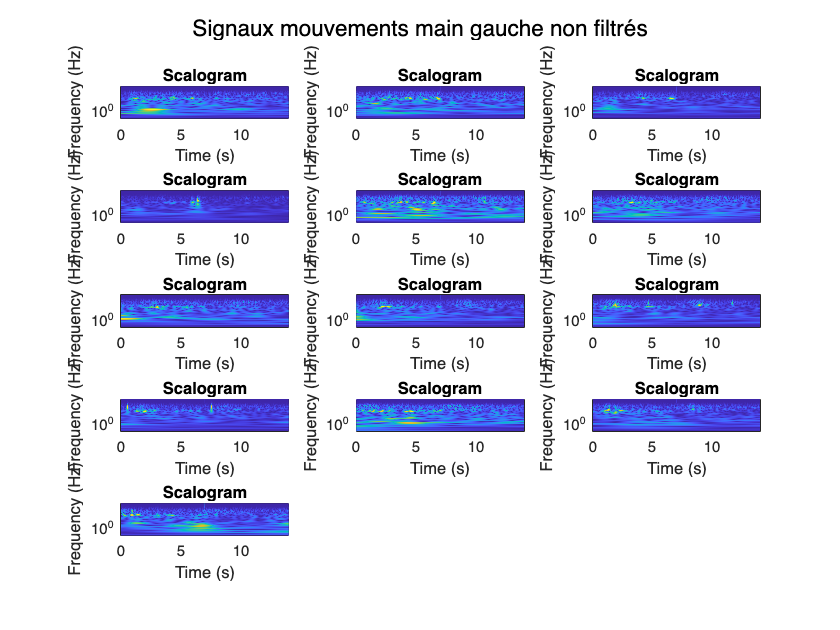


% Création de la figure pour les mouvements de la main gauche (non filtrés)
figure;
sgtitle('Signaux mouvements main gauche non filtrés');
for i = 0:12
    
    startIndexCroix = int32(decompte + nn*i);
    endIndexCroix = int32(decompte + nn*i + 7*250);
    startIndexSignal = int32(endIndexCroix);
    endIndexSignal = int32(startIndexSignal + 7*250);
    
    label = 'Gauche';
    mouvement = data(startIndexSignal:endIndexSignal, :);
    gauche = [mouvement(:,2);...
        mouvement(:,4)];
    
    subplot(5,3,i+1);
    fb = cwtfilterbank(signallength = length(gauche),...
                samplingfrequency=fs, ...
                wavelet="Morse");
    [cfs,frq] = wt(fb,gauche);
    %Tracé du scalogramme
    t = (0:(length(gauche)-1))/fs;
    pcolor(t,frq,abs(cfs));
    set(gca,'yscale','log');shading interp;axis tight;
    title('Scalogram');xlabel('Time (s)');ylabel('Frequency (Hz)');
end